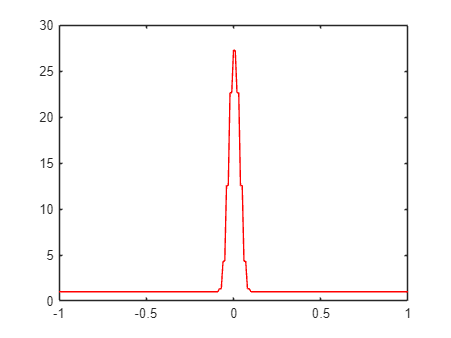

U = zeros(100000, 201);
P = zeros(100000, 201);
r = zeros(1, 201);

for i = 1:201
    P(1, i) = 1;
    if i > 101
        U(1, i) = -2;
    else
        U(1, i) = 2;
    end
end

t = 0;
dx = 1/100;
e = 0.9;
index = 0;

for j = 1:100000
    r = zeros(1, 201);
    for i = 1:201
        r(1, i) = abs(U(j, i));
    end
    sr = max(r);
    dt = (e*dx)/sr;
    t= t+dt;
    if t > 0.5
        index = j;
        break
    end
    for k = 2:200    
        P(j+1, k) = 0.5*(P(j, k+1)+P(j, k-1)) - 0.5*e/sr * (P(j, k+1) * U(j, k+1) - P(j, k-1)*U(j, k-1));
    end
    P(j+1, 1) = P(j+1, 2);
    P(j+1, 201) = P(j+1, 200);

    for k = 2:200
        U(j+1, k) = (0.5*(U(j, k+1)*P(j, k+1) + P(j, k-1)*U(j, k-1)) - 0.5*(e/sr)*(P(j, k+1) * (U(j, k+1)^2) - P(j, k-1)*(U(j, k-1))^2 ))/P(j+1, k);
    end

    U(j+1, 1) = U(j+1, 2);
    U(j+1, 201) = U(j+1, 200);
end
x_data = linspace(-1, 1, 201);
plot(x_data, P(index, :), 'red')

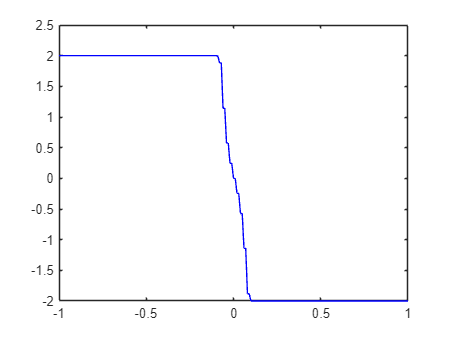

plot(x_data, U(index, :), 'blue')

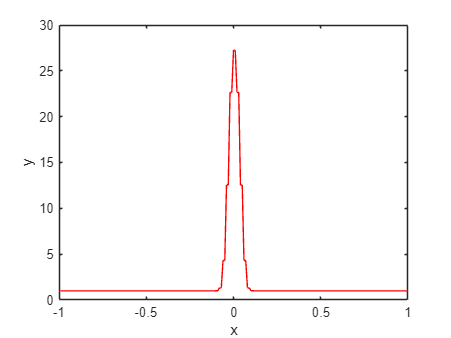


for k = 1:index
    plot(x_data, P(k, :), 'r')
    xlabel('x');
    ylabel('y');
    pause(0.1);
end